# Allgemeine Elektrotechnik 2,  Modulschlussprüfung  Juli  2017

%******************************************************************************
% \details     : 
% \autor       : Simon Burkhardt
% \file        : 
% \date        : 20.06.2018
% \version     : 1.0
%******************************************************************************
clear all; clc
format shorteng

## Aufgabe 1

% STERNSCHALTUNG MIT MITTELPUNKTSLEITER
U1m_ = 220 * cis(-120, 'deg');
U2m_ = 220 * cis(120, 'deg');
U3m_ = 220 * cis(0, 'deg');

Z1_ = 4 + j*10;
Z2_ = 5 - j*12;
Z3_ = 6 + j*5;

% a) S1 = geschlossen
I1_ = U1m_ / Z1_

I1_ =    -20.2177e+000 +  2.9129e+000i


I2_ = U2m_ / Z2_

I2_ =    -16.7829e+000 -  2.1738e+000i


I3_ = U3m_ / Z3_

I3_ =     21.6393e+000 - 18.0328e+000i



IM_ = I1_ + I2_ + I3_;

I1=strcat(num2str(abs(I1_)), "A /_ ", num2str(rad2deg(angle(I1_))), "°")

I1 = "20.4265A /_ 171.8014°"

I2=strcat(num2str(abs(I2_)), "A /_ ", num2str(rad2deg(angle(I2_))), "°")

I2 = "16.9231A /_ -172.6199°"

I3=strcat(num2str(abs(I3_)), "A /_ ", num2str(rad2deg(angle(I3_))), "°")

I3 = "28.1681A /_ -39.8056°"

IM=strcat(num2str(abs(IM_)), "A /_ ", num2str(rad2deg(angle(IM_))), "°")

IM = "23.1309A /_ -131.6134°"


S_ = U1m_*I1_' + U2m_*I2_' + U3m_*I3_'

S_ =      7.8616e+003 +  4.7029e+003i


Ptot = real(S_)

% b) S1  = offen --> Zmm = 10R

Zmm_ = 10;


## Aufgabe 2

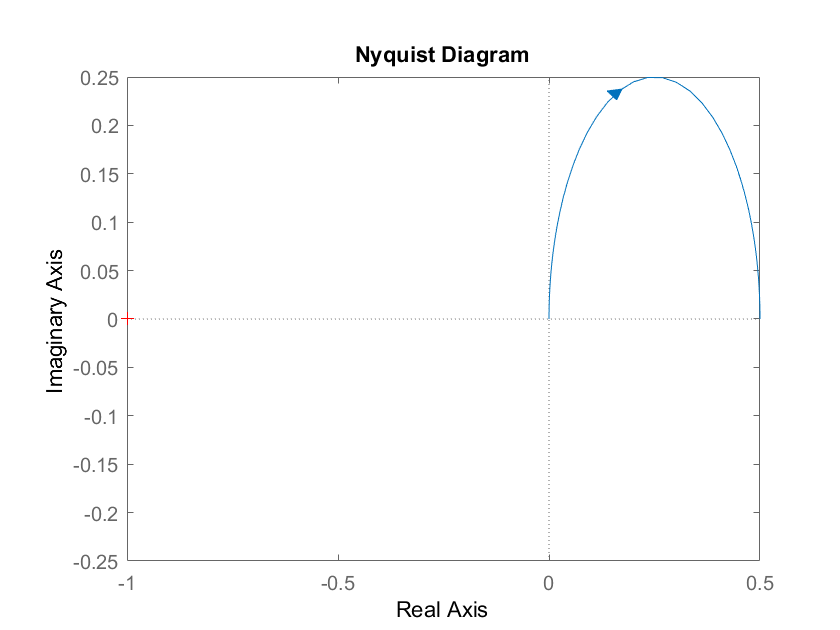

clear
R1 = 1;
R2 = 1;
C2 = 100e-9;
s=tf('s');

I2 = ( 1/( 1/(R1) + 1/(R2+1/(s*C2)) ) ) / ( R2+1/(s*C2) );
ny=nyquistplot(I2);
setoptions(ny,'ShowFullContour','off')

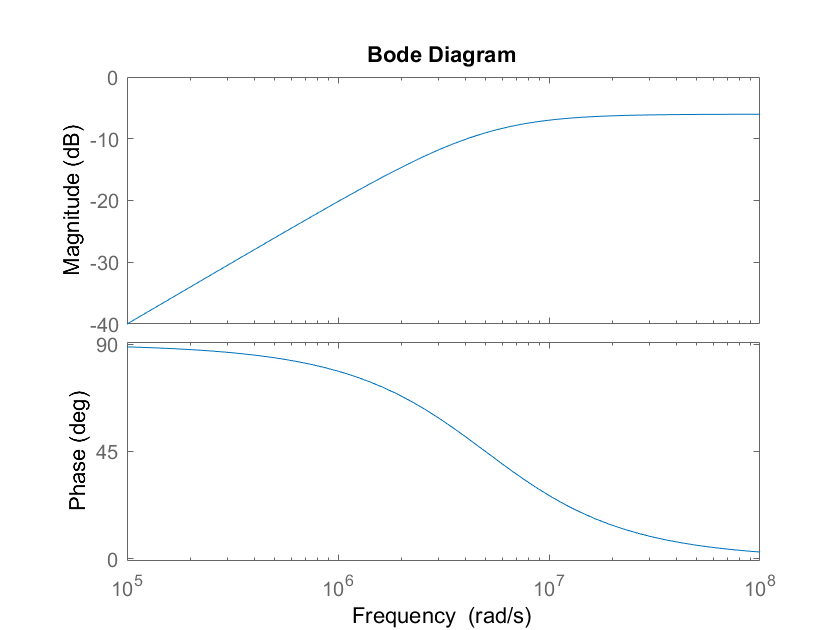

bodeplot(I2)

## Aufgabe 3

f = 1000; T = 1/f; w = 2*pi*f;
U_ = 15/sqrt(2) * cis(0, 'deg');
L = 10e-3;
C = 1e-6;
R = 80;

I1_ = U_/(R + 1/(j*w*C));
ppcomp(I1_, 'I1', 'A')

ans = "I1 = 0.059544 A cis( 63.3134° )"

I2_ = U_/(j*w*L);
ppcomp(I2_, 'I2', 'A')

ans = "I2 = 0.16881 A cis( -90° )"


%% mehrere Berechnungsarten
Pr = abs(I1_)^2*R

Pr =    283.6406e-003


Qc = abs(I1_)^2*(1/(j*w*C))

Qc =      0.0000e+000 -564.2850e-003i


Src_ = abs(I1_)^2 * (R+1/(j*w*C))

Src_ =    283.6406e-003 -564.2850e-003i


Src_ = U_ * I1_'

Src_ =    283.6406e-003 -564.2850e-003i


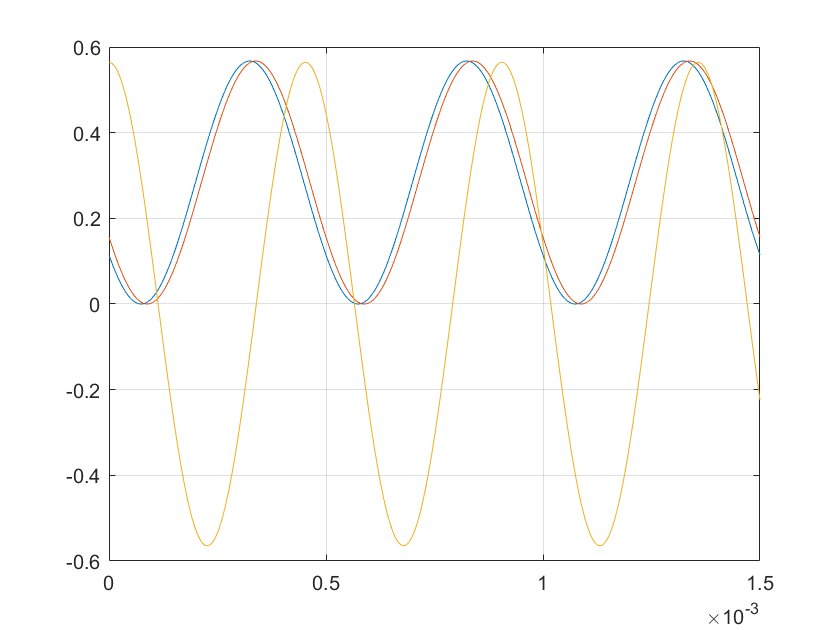


% b) visualisierung
t=linspace(0, 1.5*T, 1e3);
u=sqrt(2)*abs(U_)*cos(w*t + angle(U_));
i1=sqrt(2)*abs(I1_)*cos(w*t + angle(I1_));
i2=sqrt(2)*abs(I2_)*cos(w*t + angle(I2_));
close
% plot(t, u); hold on
% plot(t, i2*10)
pr= i1.^2.*R;
prr = Pr+Pr*cos(2*w*t+angle(Src_)+pi);
pc=abs(Qc)*cos(2*w*t*angle(Src_));
plot(t, pr); hold on; grid on
% plot(t, prr);
plot(t, pc);


% c) Resonanzfrequenz
Qc = 1/R*sqrt(L/C);
w0 = 1/sqrt(L*C);
wr = w0 * sqrt(1/(1-1/(Qc^2)))

wr =     16.6667e+003


% Kontrolle
Z_ = par(j*wr*L, R+1/(j*wr*C))

Z_ =    125.0000e+000 - 13.5525e-015i


## Aufgabe 4

clear
f = 10e6; w = 2*pi*f;
U = 50;
Rq = 1200;
Rl = 50;
C = 100e-12;

% a) Ersatzquelle
Zq_ = par(Rq, 1/(j*w*C))

Zq_ =     20.7437e+000 -156.4037e+000i


Uq_ = U / (Rq+1/(j*w*C))*(1/(j*w*C))

Uq_ =    864.3204e-003 -  6.5168e+000i


Pav = abs(Uq_)^2/(4*real(Zq_))

Pav =    520.8333e-003



% b) Leistung in der Last
Il_ = Uq_/(Zq_+Rl);
Pl = abs(Il_)^2*Rl

Pl =     73.3300e-003



% c) Anpassnetzwerke
% Rq = 20  <  Rl = 50
syms X4 X3
gl1 = Rl == 1/( 1/(j*X4) + 1/(j*X3+real(Zq_)) );
gl2 = real(Zq_) == j*X3 + 1/( 1/Rl + 1/(j*X4) );

lsg = solve(gl1, gl2);
X31 = double(lsg.X3(1))

X31 =     24.6350e+000


X41 = double(lsg.X4(1))

X41 =    -42.1020e+000


X32 = double(lsg.X3(2))

X32 =    -24.6350e+000


X42 = double(lsg.X4(2))

X42 =     42.1020e+000



L3 = X31/w

L3 =    392.0784e-009


C4 = 1/(w*abs(X41))

C4 =    378.0219e-012



L4 = X42/w

L4 =    670.0749e-009


C3 = 1/(w*abs(X32))

C3 =    646.0518e-012



% Kontrolle
Zqq = j*w*L3 + par(Rl, 1/(j*w*C4))

Zqq =     20.7437e+000


Zll = par(1/(j*w*C4), real(Zq_)+j*w*L3)

Zll =     50.0000e+000 + 17.3472e-015i



Zqq = 1/(j*w*C3) + par(Rl, j*w*L4)

Zqq =     20.7437e+000


Zll = par(j*w*L4, real(Zq_)+1/(j*w*C3))

Zll =     50.0000e+000 - 17.3472e-015i



% gäbe noch weitere Netzwerke !


## 5. unabhängige Kurzaufgaben

clear all; clc

% e)
L = 1e-3;
C = 470e-9;
R = 0.5;
w0 = 1/sqrt(L*C);
Qc = 1/(w0*C*R)

Qc =     92.2531e+000


Qneu = 0.7*Qc;
Ql = 1/( 1/Qneu - 1/Qc )

Ql =    215.2573e+000


Rp = Ql*L*w0

Rp =      9.9291e+003
